# Cross Validation

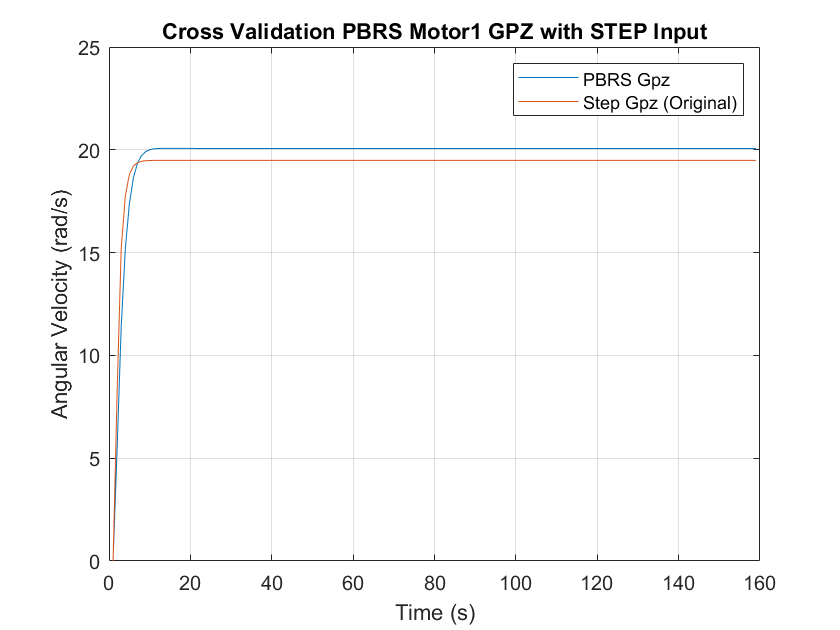

DataSTEP = xlsread("C:\Users\rodri\Documents\PY4E\Control\Reto_Control\Motor_Data\STEP_datos_excel.xlsx");
DataPBRS = xlsread("C:\Users\rodri\Documents\PY4E\Control\Reto_Control\Motor_Data\PRBS_datos_excel.xlsx");
U_STEP = DataSTEP(:,2);
U_PBRS = DataPBRS(:,2);

z = tf('z', 0.1);
Gpz_STEP_1 = (1.646*z^(2) + 1.078*z + 0.1029)/(z^3 - 0.1925*z^(2) - 0.08214*z);
Gpz_STEP_2 = (1.558*z^(2) + 1.322*z + 0.345)/(z^3 - 0.1756*z^(2) - 0.03887*z);
Gpz_PBRS_1 = (1.097*z^(2) + 0.008093*z - 0.1973)/(z^3 - 1.073*z^(2) + 0.2992*z);
Gpz_PBRS_2 = (1.033*z^(2) - 0.004355*z - 0.2917)/(z^3 - 1.171*z^(2) + 0.348*z);

compare_data_x = lsim(Gpz_PBRS_1, U_STEP);
original_data_x = lsim(Gpz_STEP_1, U_STEP);
plot(compare_data_x)
hold on
plot(original_data_x)
title('Cross Validation PBRS Motor1 GPZ with STEP Input')
legend('PBRS Gpz', 'Step Gpz (Original)')
ylabel('Angular Velocity (rad/s)');
xlabel('Time (s)');
grid on;
hold off

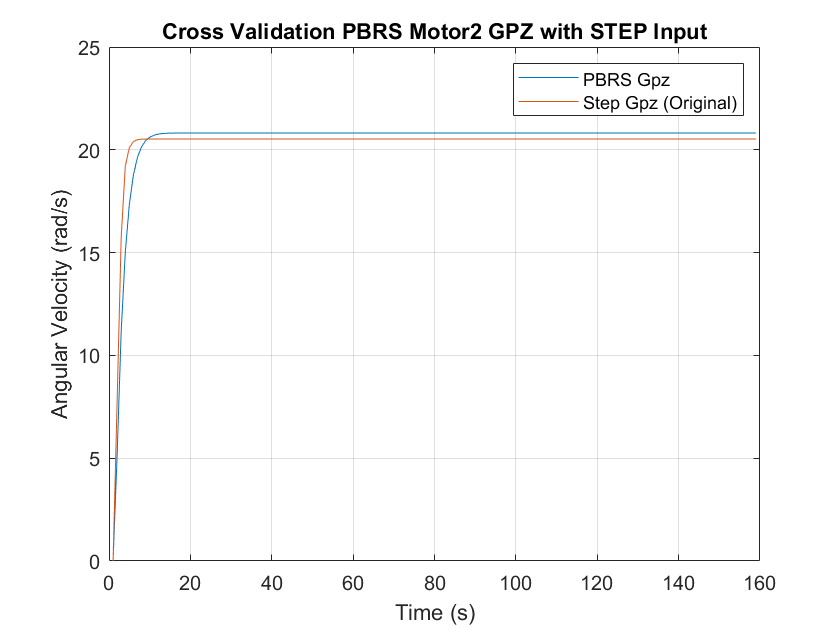


compare_data_y = lsim(Gpz_PBRS_2, U_STEP);
original_data_y = lsim(Gpz_STEP_2, U_STEP);
plot(compare_data_y)
hold on
plot(original_data_y)
title('Cross Validation PBRS Motor2 GPZ with STEP Input')
legend('PBRS Gpz', 'Step Gpz (Original)')
ylabel('Angular Velocity (rad/s)');
xlabel('Time (s)');
grid on;
hold off

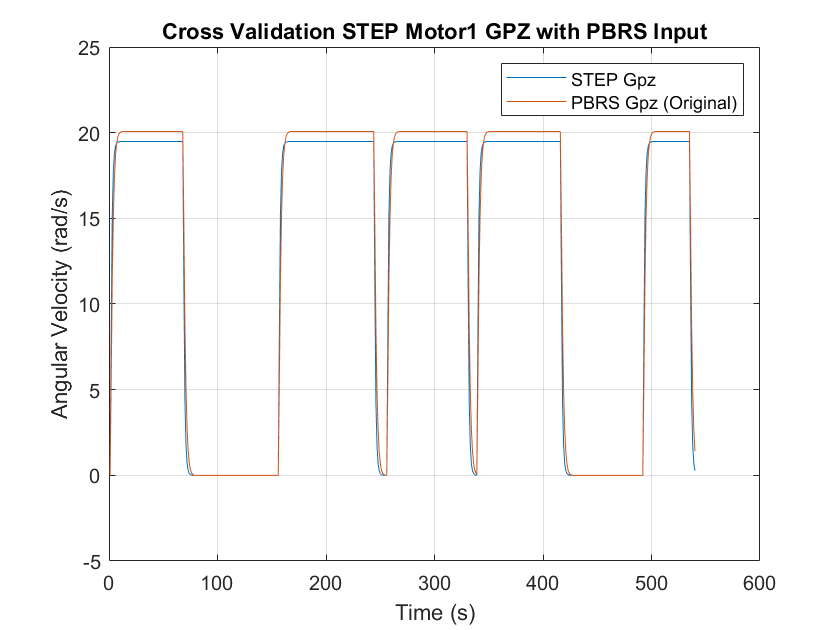


compare_data_1 = lsim(Gpz_STEP_1, U_PBRS);
original_data_1 = lsim(Gpz_PBRS_1, U_PBRS);
plot(compare_data_1)
hold on
plot(original_data_1)
title('Cross Validation STEP Motor1 GPZ with PBRS Input')
legend('STEP Gpz', 'PBRS Gpz (Original)')
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
grid on
hold off

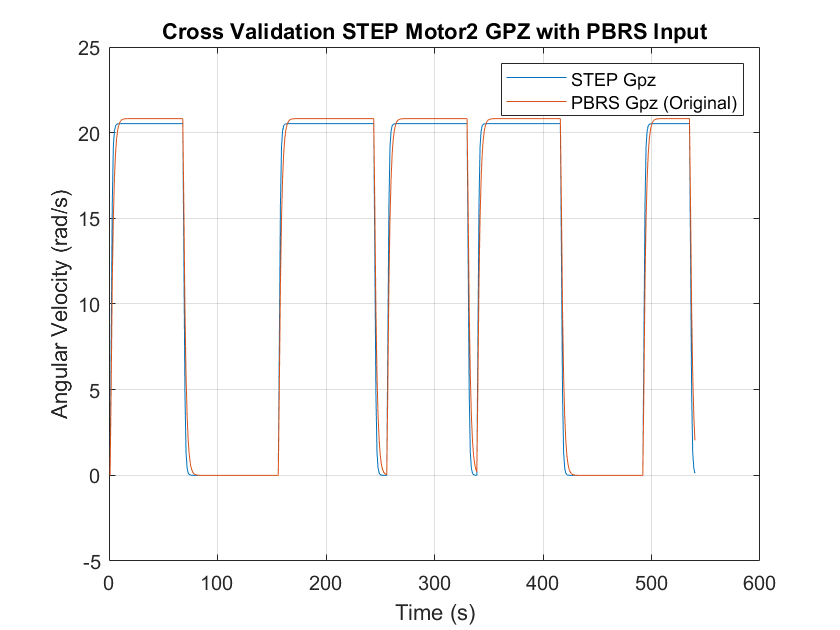


compare_data_2 = lsim(Gpz_STEP_2, U_PBRS);
original_data_2 = lsim(Gpz_PBRS_2, U_PBRS);
plot(compare_data_2)
hold on
plot(original_data_2)
title('Cross Validation STEP Motor2 GPZ with PBRS Input')
legend('STEP Gpz', 'PBRS Gpz (Original)')
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
grid on
hold off